# DynMC-SimTree搜索算法开发

接下来对每个能先到的搜索思路进行尝试并比较。首先如果没有打开并行池的话，需要把并行核心都打开。本机最大是24核心并行。

myCluster = parcluster('Processes');% 如果打不开可以先运行这个
delete(myCluster.Jobs);

parpool(20);

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 2 3 4 5 7 9 10 12 13 14 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 20 workers.


## 算法2：阶段并行广度优先搜索

每个阶段是并行运行的，会将前一个阶段的仿真结果存储起来，这样可以节省相当大的时间开销，应用了动态规划的思想。

initCurrentScenario
if isvalid(route_handle) 
    delete(route_handle) 
end
% 获取当前并行池中的核心数量
pool_current = gcp();
numWorkers = pool_current.NumWorkers;
tic
% 初始化阶段
scenarioSet = {s}; % 上次仿真得到的有效场景集合
scenarioSet{1}.egoTargetLaneIdx = s.targetLaneIdx_(1);
validCounter = 1; % 有效场景数量
currentTime = 0; 
simedSceNum = 0;
% 循环仿真阶段
for simRound = 1:14 % 一共分为14个仿真阶段，推演之后20s的未来
    if simRound <= 8 % 每次仿真的时间长度先密后疏
        incSimTime = 1;
    else
        incSimTime = 2;
    end
    % 设置本阶段要仿真到的时间
    currentTime = currentTime + incSimTime;
    
    % 先来一遍循环，检查一下有效场景个数
    last_validCounter = validCounter;
    last_scenarioSet = scenarioSet;
    for sceNum = 1:last_validCounter

    end

    validCounter = 0;
    for sceNum = 1:last_validCounter
        if ~last_scenarioSet{sceNum}.trim
        % 设置本阶段仿真时间
        last_scenarioSet{sceNum}.sectionSimTime = currentTime; 
        % 计数原有场景和新拓展场景
        addSceNum = sum(last_scenarioSet{sceNum}.ego_canLC);
        validCounter = validCounter + addSceNum + 1; 
        end
    end
    % 根据统计好的有效场景数量分配一个cell
    scenarioSet = cell(validCounter,1);
    % 将所有内容装入cell中
    loadedSceNum = 0;
    for sceNum = 1:last_validCounter
        % 先把原场景装进来
        if ~last_scenarioSet{sceNum}.trim
            loadedSceNum = loadedSceNum + 1;
            scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}; 
            ego_canLC = last_scenarioSet{sceNum}.ego_canLC;
            if ego_canLC(1)
                loadedSceNum = loadedSceNum + 1;
                scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}.setAction('L');
            end
            if ego_canLC(2)
                loadedSceNum = loadedSceNum + 1;
                scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}.setAction('R');
            end
        end
    end
    if validCounter < 200*numWorkers
        for sceNum = 1:validCounter
           scenarioSet{sceNum} = scenarioSet{sceNum}.simulate;
        end
    else
        % 计算每个核心需要处理的场景数量
        baseCount = floor(validCounter / numWorkers); % 每个核心的基本场景数
        extraCount = mod(validCounter, numWorkers);  % 需要多分配的场景数
        % results = Composite(); % 使用 Composite 存储每个 worker 的结果
        spmd 
            % 每个核心的索引
            workerIdx = spmdIndex;
            
            % 计算每个核心开始和结束的场景索引
            if workerIdx <= extraCount
                startIdx = (workerIdx - 1) * (baseCount + 1) + 1;
                endIdx = workerIdx * (baseCount + 1);
            else
                startIdx = extraCount * (baseCount + 1) + (workerIdx - extraCount - 1) * baseCount + 1;
                endIdx = extraCount * (baseCount + 1) + (workerIdx - extraCount) * baseCount;
            end
            
            % 处理分配给当前核心的场景
            localResults = cell(endIdx - startIdx + 1, 1); % 局部结果数组
            for i = startIdx:endIdx
                currentScenario = scenarioSet{i};
                localResults{i - startIdx + 1} = currentScenario.simulate(); % 执行仿真
            end
            
            % 将结果汇总回主进程
            results = localResults;

        end
        % 汇总所有 worker 的结果到主进程
        scenarioSet = cat(1, results{:});
        
    end
    disp(['第' num2str(simRound) '阶段，仿真到第' ...
       num2str(currentTime) 's，此时有' num2str(validCounter) '种情况'])
    simedSceNum = simedSceNum + validCounter*incSimTime;
    % costs = [cellfun(@(x) x.cost, scenarioSet, 'UniformOutput', true)]
end

第1阶段，仿真到第1s，此时有2种情况
第2阶段，仿真到第2s，此时有3种情况
第3阶段，仿真到第3s，此时有4种情况
第4阶段，仿真到第4s，此时有5种情况
第5阶段，仿真到第5s，此时有8种情况
第6阶段，仿真到第6s，此时有13种情况
第7阶段，仿真到第7s，此时有20种情况
第8阶段，仿真到第8s，此时有29种情况
第9阶段，仿真到第10s，此时有43种情况
第10阶段，仿真到第12s，此时有76种情况
第11阶段，仿真到第14s，此时有120种情况
第12阶段，仿真到第16s，此时有153种情况
第13阶段，仿真到第18s，此时有131种情况
第14阶段，仿真到第20s，此时有95种情况


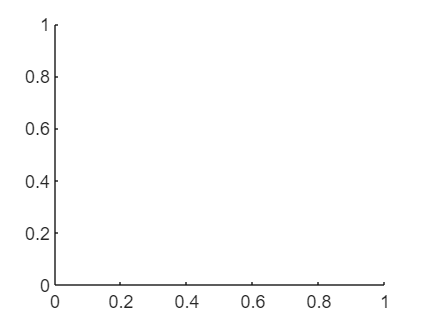


% 后处理阶段
costs = [cellfun(@(x) x.cost, scenarioSet, 'UniformOutput', true)];
[~,idx] = min(costs);
theScenario = scenarioSet{idx};
route = theScenario.getEgoRoute();
simTimeCost = toc;
% 
figure(3),hold on;
route_handle = plot(route(:,1),route(:,2),'r','LineWidth',1.5);
hold off


eqlSimNum = simedSceNum/theScenario.maxSimTime;
disp(['阶段并行深度优先搜索用时' num2str(simTimeCost) 's'])

阶段并行深度优先搜索用时3.7017s


disp(['等效仿真场景数' num2str(eqlSimNum) '个,相当于每个场景用时' num2str(round(1000*simTimeCost/eqlSimNum,2)) 'ms'])

等效仿真场景数66个,相当于每个场景用时56.09ms


## 算法5：场景并行广度优先搜索

分为14个不同场景，每个场景是并行运行的，每个场景计算内会将前一个阶段的仿真结果存储起来，这样可以节省相当大的时间开销，应用了动态规划的思想。

parpool(14)

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 2 3 4 5 7 9 10 12 13 14 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 14 workers.

ans = 

 ProcessPool - 属性: 

            Connected: true
           NumWorkers: 14
                 Busy: false
              Cluster: 

% initCurrentScenario
if isvalid(route_handle) 
    delete(route_handle) 
end
tic
% 初始化阶段
allowedPatternSet = {'R','L','RR','RL','LR','LL','RRR', ...
    'RRL','RLR','RLL','LRL','LRR','LLR','LLL'};
validCounter = 1; % 有效场景数量
currentTime = 0; 
simedSceNum = 0;
% results = Composite();
spmd % 场景并行
    scenarioSet = {s}; % 上次仿真得到的有效场景集合
    scenarioSet{1}.egoTargetLaneIdx = s.targetLaneIdx_(1);
    scenarioSet{1}.ifSceParallel = true; % 进行场景并行
    scenarioSet{1}.allowedPattern = allowedPatternSet{spmdIndex};
    % 循环仿真阶段
    for simRound = 1:14 % 一共分为14个仿真阶段，推演之后20s的未来
        if ~isempty(scenarioSet)
            if simRound <= 8 % 每次仿真的时间长度先密后疏
                incSimTime = 1;
            else
                incSimTime = 2;
            end
            % 设置本阶段要仿真到的时间
            currentTime = currentTime + incSimTime;
            
            % 先来一遍循环，检查一下有效场景个数
            last_validCounter = validCounter;
            last_scenarioSet = scenarioSet;
            validCounter = 0;
            for sceNum = 1:last_validCounter
                if ~last_scenarioSet{sceNum}.trim
                % 设置本阶段仿真时间
                last_scenarioSet{sceNum}.sectionSimTime = currentTime; 
                % 计数原有场景和新拓展场景
                addSceNum = sum(last_scenarioSet{sceNum}.ego_canLC);
                validCounter = validCounter + addSceNum + 1; 
                end
            end
            % 根据统计好的有效场景数量分配一个cell
            scenarioSet = cell(validCounter,1);
            % 将所有内容装入cell中
            loadedSceNum = 0;
            for sceNum = 1:last_validCounter
                % 先把原场景装进来
                if ~last_scenarioSet{sceNum}.trim
                    loadedSceNum = loadedSceNum + 1;
                    scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}; 
                    ego_canLC = last_scenarioSet{sceNum}.ego_canLC;
                    if ego_canLC(1)
                        loadedSceNum = loadedSceNum + 1;
                        scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}.setAction('L');
                    end
                    if ego_canLC(2)
                        loadedSceNum = loadedSceNum + 1;
                        scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}.setAction('R');
                    end
                end
            end
        
            for sceNum = 1:validCounter
               scenarioSet{sceNum} = scenarioSet{sceNum}.simulate;
            end
         
            disp(['第' num2str(simRound) '阶段，仿真到第' ...
               num2str(currentTime) 's，此时有' num2str(validCounter) '种情况'])
            simedSceNum = simedSceNum + validCounter*incSimTime;
        end
    end
    if ~isempty(scenarioSet)
        costs = zeros(length(scenarioSet),1);
        for k = 1:length(costs)
            costs(k) = scenarioSet{k}.cost;
        end
        [~,idx] = min(costs);
        results = scenarioSet{idx};
        tempCost = spmdCat(scenarioSet{idx}.cost,1,1)
    else
        results = [];
        tempCost = spmdCat(inf,1,1)
    end
end

Worker  4: 
  第1阶段，仿真到第1s，此时有2种情况
  第2阶段，仿真到第2s，此时有3种情况
  第3阶段，仿真到第3s，此时有4种情况
  第4阶段，仿真到第4s，此时有5种情况
  第5阶段，仿真到第5s，此时有7种情况
  第6阶段，仿真到第6s，此时有10种情况
  第7阶段，仿真到第7s，此时有14种情况
Worker  3: 
  第1阶段，仿真到第1s，此时有2种情况
  第2阶段，仿真到第2s，此时有3种情况
  第3阶段，仿真到第3s，此时有4种情况
  第4阶段，仿真到第4s，此时有5种情况
  第5阶段，仿真到第5s，此时有7种情况
  第6阶段，仿真到第6s，此时有10种情况
  第7阶段，仿真到第7s，此时有14种情况
Worker  5: 
  第1阶段，仿真到第1s，此时有2种情况
  第2阶段，仿真到第2s，此时有2种情况
  第3阶段，仿真到第3s，此时有2种情况
  第4阶段，仿真到第4s，此时有2种情况
  第5阶段，仿真到第5s，此时有3种情况
  第6阶段，仿真到第6s，此时有4种情况
  第7阶段，仿真到第7s，此时有5种情况
  第8阶段，仿真到第8s，此时有6种情况
  第9阶段，仿真到第10s，此时有7种情况
  第10阶段，仿真到第12s，此时有8种情况
Worker  6: 
  第1阶段，仿真到第1s，此时有2种情况
  第2阶段，仿真到第2s，此时有2种情况
  第3阶段，仿真到第3s，此时有2种情况
  第4阶段，仿真到第4s，此时有2种情况
  第5阶段，仿真到第5s，此时有3种情况
  第6阶段，仿真到第6s，此时有4种情况
  第7阶段，仿真到第7s，此时有5种情况
  第8阶段，仿真到第8s，此时有6种情况
  第9阶段，仿真到第10s，此时有7种情况
Worker  9: 
  第1阶段，仿真到第1s，此时有2种情况
  第2阶段，仿真到第2s，此时有3种情况
  第3阶段，仿真到第3s，此时有4种情况
  第4阶段，仿真到第4s，此时有5种情况
  第5阶段，仿真到第5s，此时有7种情况
  第6阶段，仿真到第6s，此时有10种情况
Worker 12: 
  第1阶段，仿真到第1s，此时有2种情况
  第2阶段，仿真到第2s，此时有2种情况
  第3阶段，仿真到第3s，此时有

% 后处理阶段
[~,minCostIdx] = min(tempCost{1});
theScenario = results{minCostIdx};
route = theScenario.getEgoRoute();
simTimeCost = toc;


% figure(3),hold on;
% route_handle = plot(route(:,1),route(:,2),'r','LineWidth',1.5);
% hold off

% eqlSimNum = simedSceNum/theScenario.maxSimTime;
disp(['场景并行广度优先搜索用时' num2str(simTimeCost) 's'])

场景并行广度优先搜索用时4.8061s


% disp(['等效仿真场景数' num2str(eqlSimNum) '个,相当于每个场景用时' num2str(round(1000*simTimeCost/eqlSimNum,2)) 'ms'])


## 算法6：场景并行广度优先局部搜索

分为14个不同场景，每个场景是并行运行的，每个场景计算内会将前一个阶段的仿真结果存储起来，这样可以节省相当大的时间开销，应用了动态规划的思想。在此基础上，在每个阶段最多只展开n种最优的情况

parpool(14);

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 2 3 4 5 7 9 10 12 13 14 33 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 14 workers.


% % initCurrentScenario
% if isvalid(route_handle) 
%     delete(route_handle) 
% end
disp(repmat('-',5,60))

------------------------------------------------------------
------------------------------------------------------------
------------------------------------------------------------
------------------------------------------------------------
------------------------------------------------------------


tic
% 初始化阶段
allowedPatternSet = {'R','L','RR','RL','LR','LL','RRR', ...
    'RRL','RLR','RLL','LRL','LRR','LLR','LLL'};
validCounter = 1; % 有效场景数量
currentTime = 0; 
simedSceNum = 0;
maxIterCaseNum = 4; % 只提取每阶段最优的n个场景展开

spmd % 场景并行
    scenarioSet = {s}; % 上次仿真得到的有效场景集合
    scenarioSet{1}.egoTargetLaneIdx = s.targetLaneIdx_(1);
    scenarioSet{1}.ifSceParallel = true; % 进行场景并行
    scenarioSet{1}.allowedPattern = allowedPatternSet{spmdIndex};
    % 循环仿真阶段
    for simRound = 1:14 % 一共分为14个仿真阶段，推演之后20s的未来
        if ~isempty(scenarioSet)
            if simRound <= 8 % 每次仿真的时间长度先密后疏
                incSimTime = 1;
            else
                incSimTime = 2;
            end
            % 设置本阶段要仿真到的时间
            currentTime = currentTime + incSimTime;

            % 先来一遍循环，检查一下有效场景个数
            last_validCounter = validCounter;
            last_scenarioSet = scenarioSet;
            noneTrimmedIdxSet = zeros(last_validCounter,1);
            ntCounter = 0;
            for sceNum = 1:last_validCounter
                if ~last_scenarioSet{sceNum}.trim
                    ntCounter = ntCounter + 1; 
                    noneTrimmedIdxSet(ntCounter) = sceNum;
                end
            end
 
            % 统计一下上一阶段所有场景的代价，找代价最小的maxIterCaseNum个场景
            costs = zeros(ntCounter,1);
            for i = 1:ntCounter
                sceNum = noneTrimmedIdxSet(i);
                costs(sceNum) = last_scenarioSet{sceNum}.cost;
            end
            [~,idxs] = sort(costs);
            realValidCaseNum = min(ntCounter,maxIterCaseNum); 

            % 先来一遍循环，检查一下有效场景个数
            validCounter = 0;
            for i = 1:realValidCaseNum
                sceNum = idxs(i);
                % 设置本阶段仿真时间
                last_scenarioSet{sceNum}.sectionSimTime = currentTime; 
                % 计数原有场景和新拓展场景
                addSceNum = sum(last_scenarioSet{sceNum}.ego_canLC);
                validCounter = validCounter + addSceNum + 1; 
            end
            
            % 根据统计好的有效场景数量分配一个cell
            scenarioSet = cell(validCounter,1);
   
            % 将所有内容装入cell中
            loadedSceNum = 0;
            for i = 1:realValidCaseNum
                sceNum = idxs(i);
                % 先把原场景装进来
                loadedSceNum = loadedSceNum + 1;
                scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}; 
                ego_canLC = last_scenarioSet{sceNum}.ego_canLC;
                if ego_canLC(1)
                    loadedSceNum = loadedSceNum + 1;
                    scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}.setAction('L');
                end
                if ego_canLC(2)
                    loadedSceNum = loadedSceNum + 1;
                    scenarioSet{loadedSceNum} = last_scenarioSet{sceNum}.setAction('R');
                end

            end

        
            for sceNum = 1:validCounter
               scenarioSet{sceNum} = scenarioSet{sceNum}.simulate;
            end
         
            disp(['第' num2str(simRound) '阶段，仿真到第' ...
               num2str(currentTime) 's，此时有' num2str(validCounter) '种情况'])
            simedSceNum = simedSceNum + validCounter*incSimTime;
        end
    end
    if ~isempty(scenarioSet)
        costs = zeros(length(scenarioSet),1);
        for k = 1:length(costs)
            costs(k) = scenarioSet{k}.cost;
        end
        [~,idx] = min(costs);
        results = scenarioSet{idx};
        tempCost = spmdCat(scenarioSet{idx}.cost,1,1);
    else
        results = [];
        tempCost = spmdCat(inf,1,1);
    end

end

Error detected on worker 17.

原因:
    错误使用 DynMC_SimTree_DEV
    索引超过数组元素的数量。索引不能超过 14。

% 后处理阶段
[~,minCostIdx] = min(tempCost{1});
theScenario = results{minCostIdx};
route = theScenario.getEgoRoute();
simTimeCost = toc;

% figure(3),hold on;
% route_handle = plot(route(:,1),route(:,2),'r','LineWidth',1.5);
% hold off

% eqlSimNum = simedSceNum/theScenario.maxSimTime;
disp(['场景并行广度优先搜索用时' num2str(simTimeCost) 's'])
% disp(['等效仿真场景数' num2str(eqlSimNum) '个,相当于每个场景用时' num2str(round(1000*simTimeCost/eqlSimNum,2)) 'ms'])



figure(3),hold on;
route_handle = plot(route(:,1),route(:,2),'r','LineWidth',1.5);
hold off



delete(route_handle)

figure(1),hold on
compassRoute_handle = plot3(route(:,1),route(:,2),linspace(0.5,10,length(route)),'r','linewidth',1.5);

delete(compassRoute_handle)